**Laboratorium 9 - Identyfikacja**

**Jakub Szczypek nr 405912**

**grupa 5 WEAIiIB air**

Obiekt inercyjny I rzędu z opóźnieniem – metoda doświadczalna

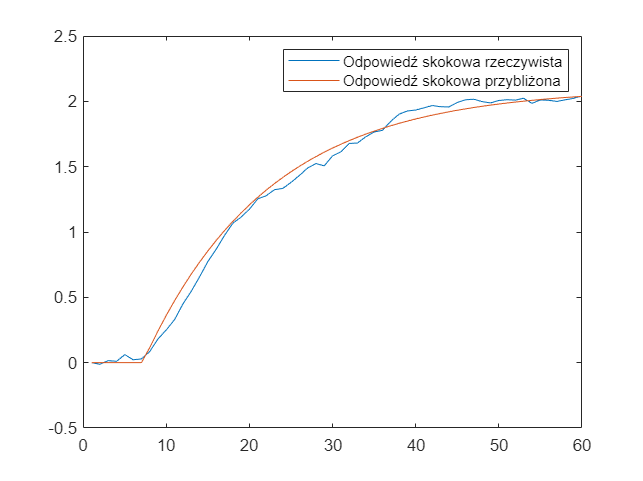

load obiekt; 
k = 2.1;
T = 15;
theta = 7.15;
t = 1:60;
model = tf([0 k], [T 1]); set(model,'outputdelay', theta); y_sym = step(model, t); plot(t,y,t,y_sym);
legend('Odpowiedź skokowa rzeczywista','Odpowiedź skokowa przybliżona')


e = y - y_sym;
blad = sum(e.^2) / length(e)

blad = 0.0034

Obiekt inercyjny I rzędu z opóźnieniem – metoda numeryczna

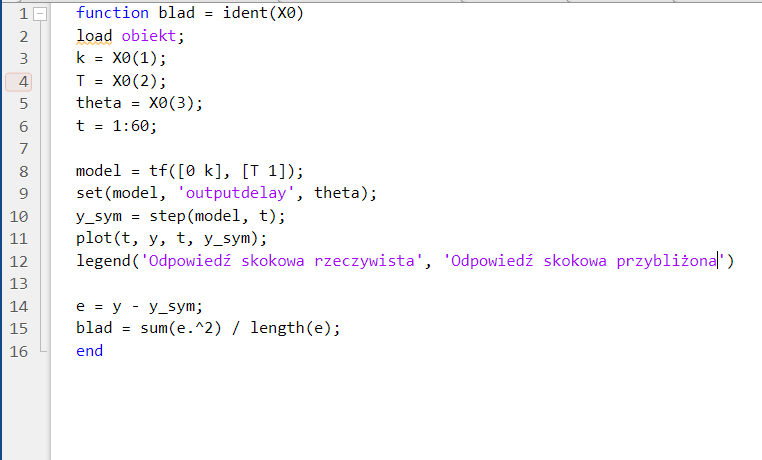

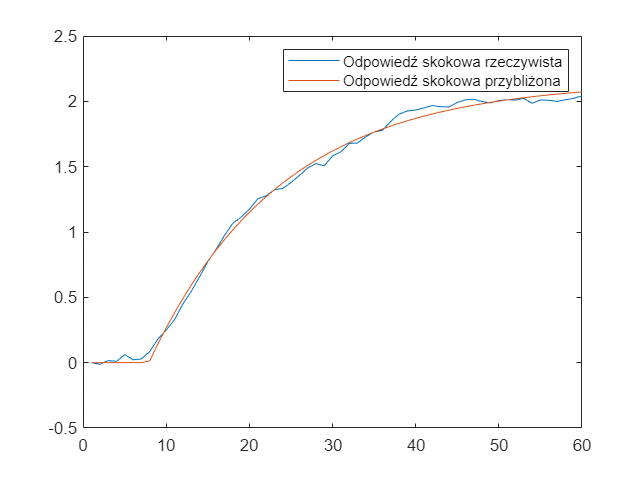

parametry =     2.1516   15.8017    7.8954


blad = 0.0015

[parametry, blad] = fminsearch('ident',[2, 15 ,7])

Obiekt inercyjny II rzędu z opóźnieniem – metoda doświadczalna

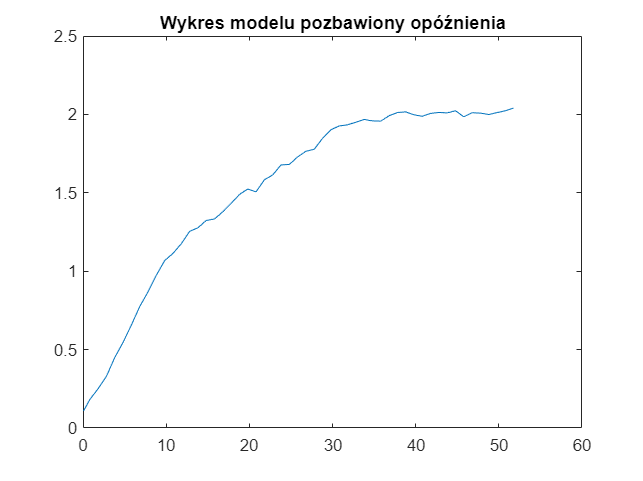

clear all, close all
load("obiekt.mat")
t = transpose(1:60);
delay = 8.2057;
T = 17.54;
t_prim = t-delay;
plot(t_prim,y)
axis([0 60 0 2.5])
title("Wykres modelu pozbawiony opóźnienia")

k = 2; % z rysunku
y_ta = 0.714*k     % szukamy warrtości t dla któtego y = 0.714*k

y_ta = 1.4280

t_a = 17.71        % odczytano, przybliżając wykres

t_a = 17.7100

t_b = t_a/4

t_b = 4.4275

y_tb = 0.496;      % odczytano, przybliżając wykres
z_tabeli = y_tb/k

z_tabeli = 0.2480


% z tabeli odczytujemy, że stosunek wynosi:
%T2/T1 = 0
T2 = 0

T2 = 0

T1 = t_a/1.2 -T2

T1 = 14.7583

Powyższe dane zostały odczytane z wykresu modelu pozbawionego opóźnienia.

Model B - metoda 2.2

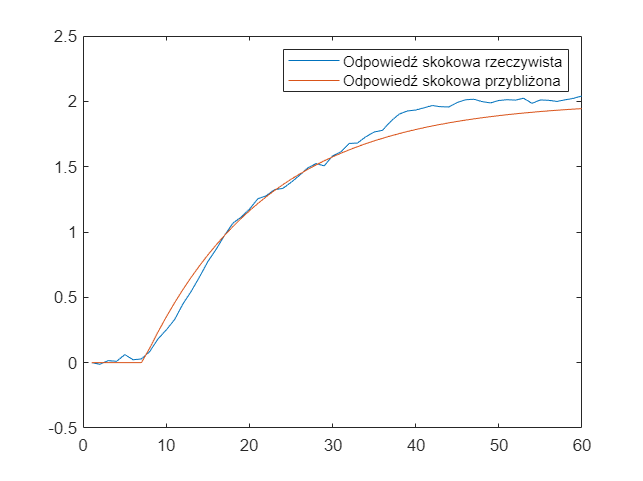

k = 2;
T1 = 14.7583;
T2 = 0;
theta = 7.15;
t = 1:60;
model = tf([0 0 k], conv([T1 1], [T2 1])); set(model,'outputdelay', theta);
y_sym = step(model, t); plot(t,y,t,y_sym);
legend('Odpowiedź skokowa rzeczywista','Odpowiedź skokowa przybliżona')

Obiekt inercyjny II rzędu z opóźnieniem – metoda numeryczna

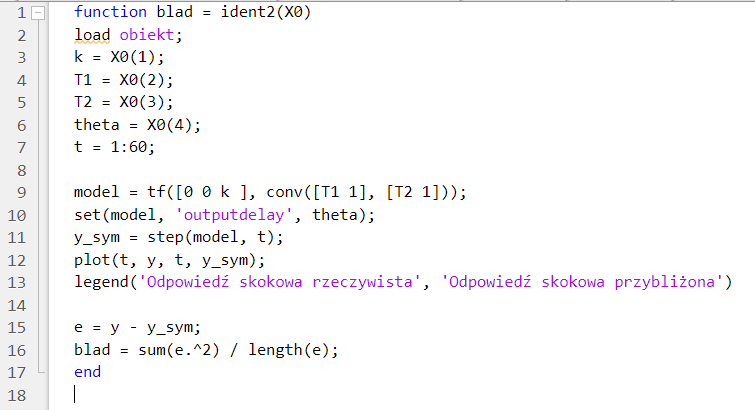

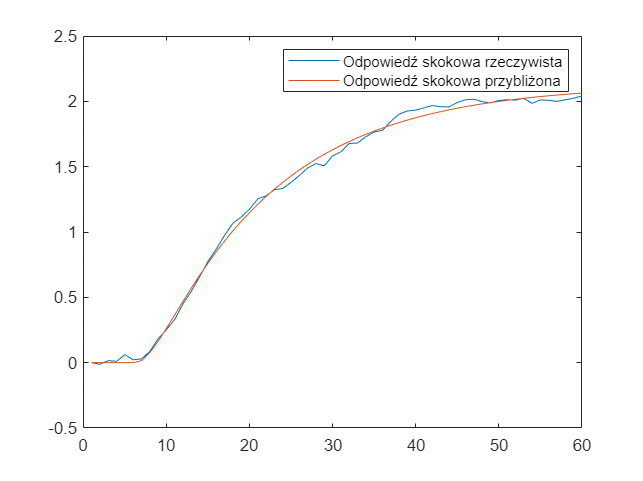

parametry =     2.1292   14.8405    2.0541    6.2836


blad = 0.0013

[parametry, blad] = fminsearch('ident2',[2, 15, 3, 7])

Obiekt wieloinercyjny bez opóźnienia - metoda numeryczna

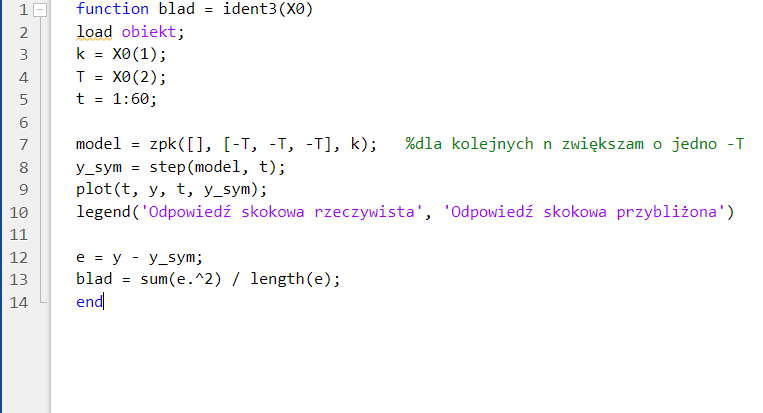

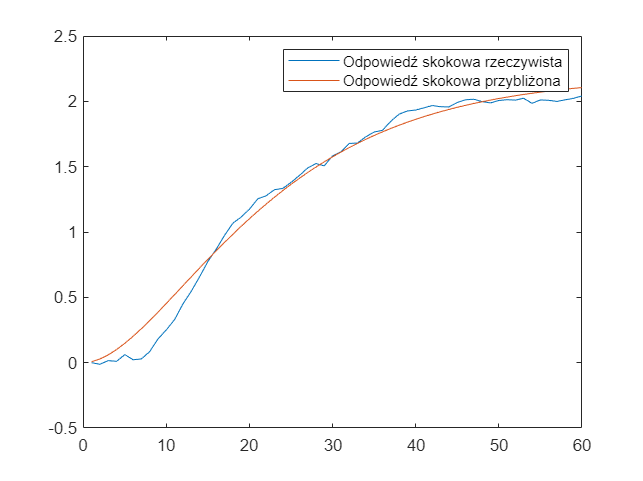

parametry =     0.0156    0.0845


blad = 0.0073

% n = 2
[parametry, blad] = fminsearch('ident3',[k,T])

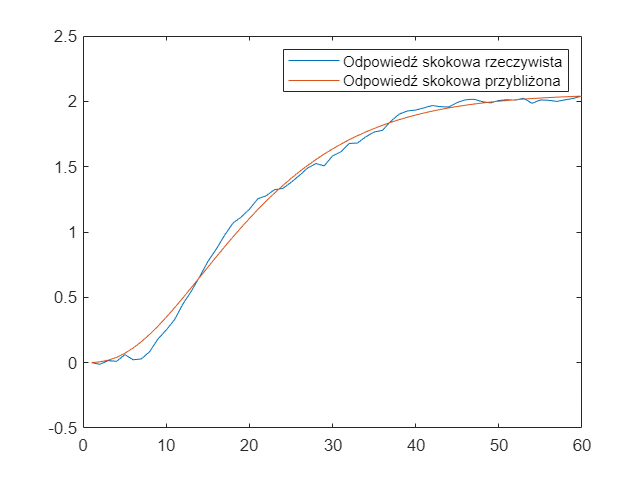

parametry =     0.0058    0.1412


blad = 0.0027

% n = 3
[parametry, blad] = fminsearch('ident3',[k,T])

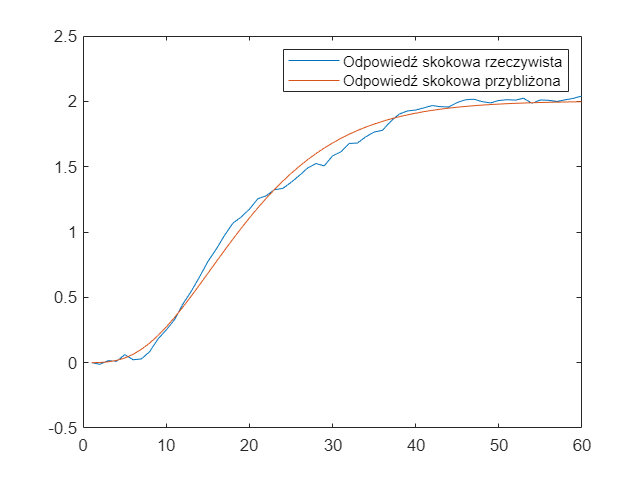

parametry =     0.0030    0.1967


blad = 0.0032

% n = 4
[parametry, blad] = fminsearch('ident3',[k,T])

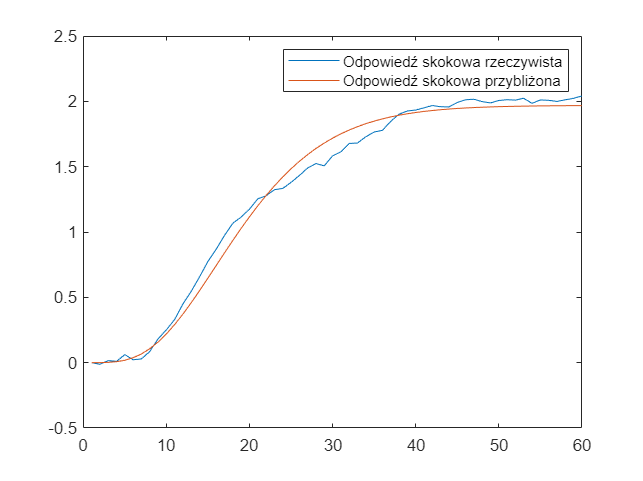

parametry =     0.0020    0.2521


blad = 0.0055

% n = 5
[parametry, blad] = fminsearch('ident3',[k,T])

Najmniejsza wartość błędu wyszła dla n = 3